
rng(0);
N = 10

N = 10

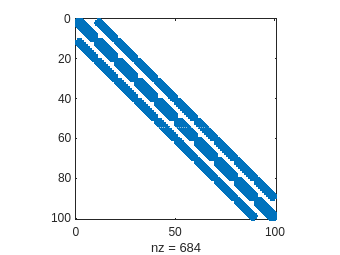

b = rand(N^2,1);
A = konv_diff(N,1e-10);
spy(A)

alpha = 1e-10 ;
B = A  + alpha * eye(size(A));

[~,flagc,~ ,~ ,resvecc] = cgs(A, b, 1e-10, 500);

[~,flagb,~ ,~ ,resvecb] = bicg(A, b, 1e-10, 500);
[~,flagc2,~ ,~ ,resvecc2] = cgs(B, b, 1e-10, 500);
[~,flagb2,~ ,~ ,resvecb2] = bicg(B, b, 1e-10, 500);


flagc, flagb

flagc = 3

flagb = 0

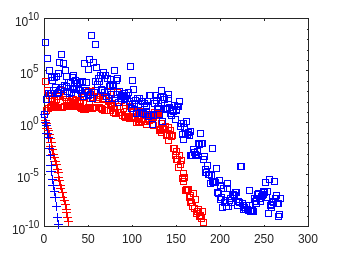

cond
semilogy(resvecb, 'sr')
hold on;
semilogy(resvecc, 'sb')
semilogy(resvecb2, '+r')
semilogy(resvecc2, '+b')
hold off;

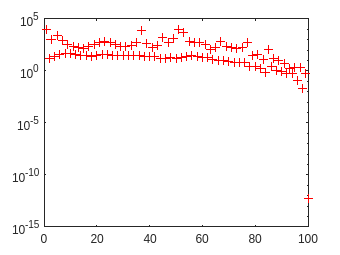



[~, re] = FOM_Session(A, b, zeros(size(b)), 1e-8,300);
semilogy(re, "+r")

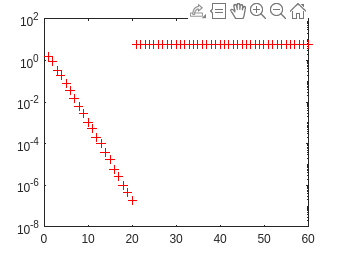

[~, re] = RFOM_Session(B, b, zeros(size(b)), 20, 3, 1e-8);
semilogy(re, "+r")